# Generating Cell Meshes and Calculating Metrics

In this script we generate cell surface meshes for the taste cells listed in the idT table (found in the [Lysosome Analysis folder](matlab:open('./idT.mat'))). These are cells that have had their lysosomes segmented. 

We use three mesh-generating steps: The first step, Alpha Shape, generates the base mesh. The following steps, manifoldPlus and MeshFix, plug up any holes in the original mesh to generate a watertight mesh. Meshes for each stage are saved in the cellMeshes folder. Note: due to the complexity of the cells, most meshes are not completely watertight. Employing the secondary mesh steps ensures most holes in the mesh are closed and overall improved volume calculation. 

Meshes are then visually inspected, and the best Mesh for cell is selected.

Metrics, such as Volume and Surface area, are then calculated from the best mesh and saved in the ***cellT*** table. 

General Impressions for each Mesh Method:

- **AlphaShape** generates the most representative shape, but the surface may be riddled with holes, which  significantly affects the volume calculation.  While these holes can be closed up by adjusting AlphaShape alpha setting, the resultant mesh is less representative of the cell's overall morphology (all the fine details get overly smoothed over) and the volume calculations maybe adversely affected. So, we call the **alphaShape **function without any alpha setting to ensure the best reconstruction of cell morphology

- **manifoldPlus** does a good job of closing up small holes while maintaining the cell's overall morphology. While, there is some degradation in the ultrastructure of the cell, volume calculations are improved.

- **MeshFix** is needed to close up large holes or holes not sealed up by manifoldPlus. However, This method may result in some noticeable degradation in the ultrastructure of the cell, but the overall volume calculation remains robust

## Setup

### Add Path

Cell Meshes will be created and stored here

clearvars -except paths proj
paths.cellMesh = fullfile(paths.lysosome,"cellMeshes");

### Load necessary variables

Vertices imported from the Reconstruct data are stored in the VL table. The idT table contains identifying information, like the name of the cell, its type (e.g, I, II, or III), and its health (e.g. healthy, early dying, late dying). 

VL = load_lys_data(paths)

## Generate Cell Meshes

The function **generateCellMeshes** generates cell meshes using alphaShape, manifoldPlus, and MeshFix. The function automatically saves these surface meshes as OBJ files in the cell Meshes folder. The function returns a table, ***meshT***, with the following fields

- **Cell**: name of cell

- **VolAS, VolMP, VolFX: ** the calculated volumes for each surface mesh

- **Method: **The surface mesh to use for calculating cell metrics. By default, the method is set to "MP" unless VolAS is greater than the other two volumes. That being said, meshes need to be visually inspected to ensure the best mesh method is selected.

meshT = generateCellMeshes(VL, paths);

meshT file found and loaded. Using this table for the analysis.##################### Arguments #####################
depth: 6.
input: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP44_EM_as.obj.
output: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP44_EM_mp.obj.
#####################################################
vertex number: 11722    face number: 24666
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 890    
Iter 1 with active vertex number 890    
Iter 2 with active vertex number 700    
Iter 3 with active vertex number 283    
Iter 4 with active vertex number 235    
Iter 5 with active vertex number 222    
Iter 6 with active vertex number 209    
Iter 7 with active vertex number 189    
Iter 8 with active vertex number 186    
Iter 9 with active vertex number 188    
Iter 10 with active vertex number 178  

save(meshT.Properties.UserData.path,"meshT");

### Generate only a subset of meshes

mt = generateCellMeshes(VL,idT(1,:),paths) % e.g. just first row in idT

##################### Arguments #####################
depth: 6.
input: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP16_EM_as.obj.
output: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP16_EM_mp.obj.
#####################################################
vertex number: 8353    face number: 16764
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 1212    
Iter 1 with active vertex number 1212    
Iter 2 with active vertex number 867    
Iter 3 with active vertex number 293    
Iter 4 with active vertex number 233    
Iter 5 with active vertex number 202    
Iter 6 with active vertex number 186    
Iter 7 with active vertex number 167    
Iter 8 with active vertex number 147    
Iter 9 with active vertex number 141    
Iter 10 with active vertex number 142    
Iter 11 with active vertex number 140    
Iter 12 with acti

## Inspect Cell Meshes

Once **generateCellMeshes** is complete, it is critical to inspect all of the meshes, especially those that have radically different volume calculations between the various methods.  

In this code block, you select the row in meshT that you would like to inspect and the function **displayCellMeshes** will display the corresponding surface meshes using the  **surfaceMeshShow** function. 

Method Guidelines: 

- If VolAS is equal or greater than the other two volumes, use the AS method

- If VolFX is significantly greater than the other two volumes, use the FX method. There is likely  a large hole somewhere in the mesh

Note: you change the set mesh method in the next code block

1. TB1_IMMCell09_CM_ry_as.obj - 0


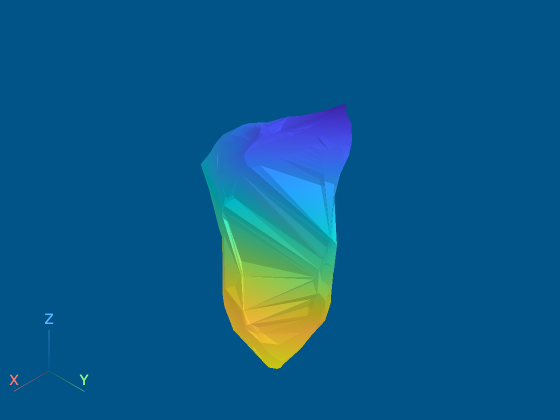

2. TB1_IMMCell09_CM_ry_fx.obj - 0
3. TB1_IMMCell09_CM_ry_mp.obj - 0


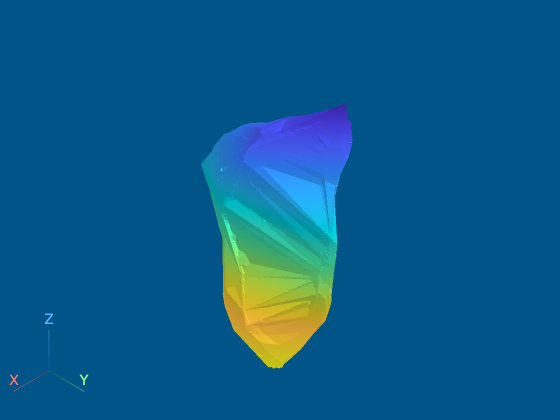

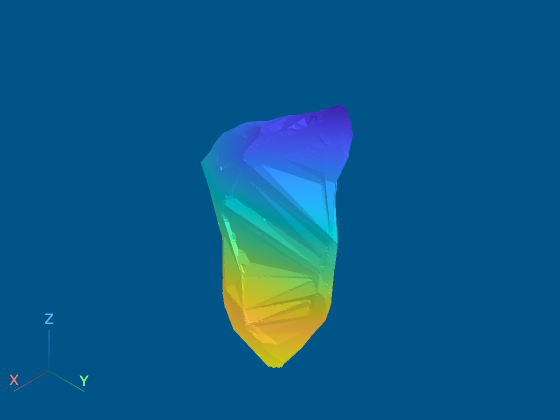

ans =   LinkProp with properties:

          Enabled: 'on'
    PropertyNames: {'CameraPosition'  'CameraZoom'}
          Targets: [1×3 Viewer3D]


mt_row = 30;
hvwr = displayCellMeshes(meshT.Object(mt_row),paths.cellMesh);

### Overlay AS and MP meshes

to double-check if needed

hp = overlayCellMeshes(paths, meshT.Object(mt_row));

### Update method for selected row

The method will be used to indicate which cell mesh is used to calculate the cell metrics like volume and surface in the next step.

method = "fx";
meshT.Method(mt_row) = method;
save(meshT.Properties.UserData.path,"meshT")
fprintf('%d. %s changed to %s.\n',mt_row,meshT.Object(mt_row),method)

## Capture Cell Metrics

### Update Cell names

replace two of the dying cells with their more complete versions that include the "bits", or apical ends. These meshes were generated using the 

replace(meshT.Cell,"TB2_TCdying-01_cw","TB2_TCdying-01")

### create cellT table

cellT = calcCellMetrics(mestT,paths)

# Local Functions

function meshT = generateCellMeshes(VL, paths)
%GENERATECELLMESHES Generate Surface Meshes from which cell volumes will be
%calculated. For each cell, three different meshes will be created: AS, MP,
%FX, each representing a different stage in mesh generation. AS, or
%AlphaShape represents the first stage of mesh generation. This mesh is
%representative of cell morphology but may containing numerous holes in surface, 
% leading to miscalculation of volume. MP, or manifoldPlus, is the first attempt to 
% repair any holes found in the surface. FX, or pymeshfix, is the final
% attempt to repair holes. This version may be more ragged looking than AS
% but more watertight. 
%
% OUTPUT:
%   meshT: table containing the following fields
%          - Object: ID of Cell
%          - VolAS, VolMP, VolFX: calculated volumes from each mesh stage.
%          - Method:  used to indicate which mesh is the most representative of the cell

arguments
    VL table % vertices list table
    paths struct % structure containing project relevant paths
end


if exist(fullfile(paths.cellMesh,"meshT.mat"),'file')
    fprintf('meshT file found and loaded. Using this table for the analysis.')
    load(fullfile(paths.cellMesh,"meshT.mat"),"-mat","meshT")
    meshT{:,{'VolAS','VolMP','VolFX'}} = nan(height(meshT),3);
    count=height(meshT);

else
    idT = VL.Properties.UserData.idT;
    idT = sortrows(idT,["Type","Health"]);
    meshT = idT(:,{'Cell','Type','Health'});
    count=height(meshT);
    meshT.Method = repmat("mp",count,1);
    meshT = movevars(meshT,'Method','After','Mesh');
    meshT = [meshT array2table(nan(count,3),'VariableNames',["VolAS","VolMP","VolFX"])];
end


hwb = waitbar(0,"Please Wait");
for n=1:count
    mesh_name = meshT.Cell(n);

    % get trace vertices
    vCell = getVertsAndAlign(VL, mesh_name,1); % align point clouds to axes

    % calculate alphaShape and then surface mesh object
    shp = alphaShape(vCell);

    [volMP, volFX] = getWaterTightMesh(shp,mesh_name, paths);

    meshT.VolAS(n) = shp.volume;
    meshT.VolMP(n) = volMP;
    meshT.VolFX(n) = volFX;
       
    waitbar(n/count, hwb,sprintf('%d. %s',n,mesh_name))

end

la = meshT.VolAS > meshT.VolFX;% volumes that get smaller indicate increase in raggedness in surface
meshT.Method(la) = "as"; % so, just use the alphaSurface
meshT.Properties.UserData.path = fullfile(paths.cellMesh,"meshT.mat");

delete(hwb)
end


## Overlay Meshes using Patch

function hp = overlayCellMeshes(paths, object)
% meshT.Object(mt_row)

contents = dir(fullfile(paths.cellMesh,object+"*.obj*"));
mmfig;

mesh = readSurfaceMesh(fullfile(paths.cellMesh, contents(1).name));
hp(1) = patch(Faces=mesh.Faces,Vertices=mesh.Vertices, ...
    FaceColor='c', ...
    FaceAlpha = 0.5,...
    edgeAlpha = 0.2);
hp(2) =  patch(Faces=mesh.Faces,Vertices=mesh.Vertices, ...
    FaceColor='m', ...
    FaceAlpha = 0.75,...
    edgeAlpha = 0.2);
axis equal off
end



## Calculate Cell Metrics

Metrics used in analysis

function cellT = calcCellMetrics(mestT,paths)

cellT = mestT(:,{'Cell','Type','Health'});

for n=1:height(mestT)

    fullpath = fullfile(paths.cellMesh,mestT.Mesh(n)+sprintf('_%s.obj',mestT.Method(n)));
    mesh = readSurfaceMesh(fullpath);

    cellT.Volume(n) = meshVolume(mesh.Vertices, mesh.Faces);
    cellT.SurfaceArea(n) = meshSurfaceArea(mesh.Vertices, mesh.Faces);
    cellT.SAV(n) = cellT.Volume(n)./cellT.SurfaceArea(n);
    fprintf('%d. %s.\n',n,mestT.Mesh(n))

end
cellT.Properties.UserData.path = fullfile(paths.lysosome,"dyingT.mat");

end
